# **demo13 of Im2mesh package**

demo13 - How to use Gmsh as mesh generator in Im2mesh package

Cite as: Ma, J., & Li, Y. (2025). Im2mesh: A MATLAB/Octave package for generating finite element mesh based on 2D multi-phase image (2.1.5). Zenodo. [https://doi.org/10.5281/zenodo.14847059](https://doi.org/10.5281/zenodo.14847059)

Jiexian Ma, mjx0799@gmail.com

## Note

I suggest familiarizing yourself with Im2mesh_GUI before learning Im2mesh package. With graphical user interface, Im2mesh_GUI will help you better understand the workflow and parameters of Im2mesh package.

Im2mesh_GUI: [https://www.mathworks.com/matlabcentral/fileexchange/179684-im2mesh_gui-2d-image-to-finite-element-mesh](https://www.mathworks.com/matlabcentral/fileexchange/179684-im2mesh_gui-2d-image-to-finite-element-mesh)

If you are using Im2mesh package in MATLAB,  you need to install MATLAB Image Processing Toolbox and Mapping Toolbox because Im2mesh package use a few functions in these toolboxes.

**Before starting, you need to download Gmsh (**[**https://gmsh.info**](https://gmsh.info)**) and un-zip.**

## Setup

Before we start, please set folder "Im2mesh_Matlab" as your current folder of MATLAB.

clearvars

Set default image size.

x = 250; y = 250; width = 250; height = 250;
set(groot, 'DefaultFigurePosition', [x,y,width,height])
% To reset:
% set(groot, 'DefaultFigurePosition', 'factory')

We add the folder 'mesh2d-master' to the path of MATLAB. 

addpath(genpath('mesh2d-master'))

**We need to know the location of gmesh.exe**

% for example
path_to_gmsh = 'C:\Users\majie\Documents\gmsh-4.13.1-Windows64\gmsh.exe';

## Get boundries from image

We have demostrate how to do this in demo04.

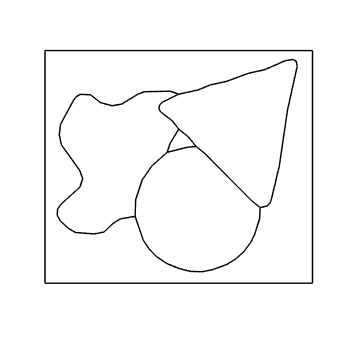

im = imread("Shape.tif");
if size(im,3) == 3;  im = rgb2gray( im ); end

% image to polygon boundary
boundsRaw = im2Bounds( im );
boundsCtrlP = getCtrlPnts( boundsRaw, false, size(im) );

% smooth boundary
lambda = 0.5;   mu = -0.5;  iters = 100;
threshold_num_turning = 0;    threshold_num_vert_Smo = 0;
boundsSmooth = smoothBounds( boundsCtrlP, lambda, mu, iters, ...
                threshold_num_turning, threshold_num_vert_Smo );

% simplify polygon boundary
tolerance = 0.3;    threshold_num_vert_Sim = 0;
boundsSimplified = simplifyBounds( boundsSmooth, tolerance, ...
                                        threshold_num_vert_Sim );
boundsSimplified = delZeroAreaPoly( boundsSimplified );

% clear up redundant vertices
% only control points and turning points will remain
boundsClear = getCtrlPnts( boundsSimplified, false );
boundsClear = simplifyBounds( boundsClear, 0 );

plotBounds( boundsClear );

## Phase selection before meshing

Suppose we don't need the background.

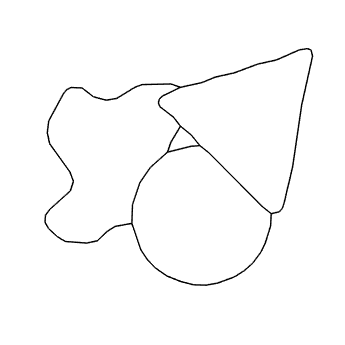

select_phase = [2 3 4];
boundsClear = boundsClear( select_phase );
plotBounds( boundsClear );

## Print geo file for Gmsh

Before printing geo file, we need to obtain surface loops from polygonal boundaries since Gmsh use loops to define suface. 

We use function bound2SurfaceLoop to convert polygonal boundaries to surface loops.

[ phaseLoops, vertex, edge ] = bound2SurfaceLoop( boundsClear );

% rename variables to be consistent with gmsh
point = vertex;
line = edge;

geo file is the input file for Gmsh. We use function printGeo to print surface loops to geo file. We will see a geo file 'gmshTemp.geo' in the current working folder of MATLAB. 

Please refer to 'Im2mesh_GUI Tutorial.pdf' and Gmsh manual about how to choose meshing parameters.

% setup parameters
opt.sizeMin = 0.1;
opt.sizeMax = 6;
opt.algthm = 6;
opt.recombAll = 0;
opt.recombAlgthm = 3;
opt.eleOrder = 1;

path_to_geo = 'gmshTemp.geo';
printGeo( phaseLoops, point, line, opt, path_to_geo );

## Generate mesh via Gmsh

We use the following command to send the geo file to Gmsh. Gmsh will generate a m file 'gmshTemp.m'. 

path_to_m = 'gmshTemp.m';
verbosity = 3;

str=sprintf('"%s" "%s" -o "%s" -v %i -save', ... 
			path_to_gmsh, path_to_geo, path_to_m, verbosity );
system(str);

When we run the m file, we will see a struct variable 'msh' in the workspace of MATLAB.

% run m file
run(path_to_m)
msh

msh = struct with fields:
        nbNod: 398
          POS: [398×3 double]
          MAX: [87.2400 77.4400 0]
          MIN: [4.6900 4.4500 0]
    TRIANGLES: [716×4 double]


## Plot mesh

Before ploting the mesh, we need to do some processing to the mesh data. 

vert = msh.POS(:,1:2);
ele = msh.TRIANGLES(:,1:end-1);
tnum = msh.TRIANGLES(:,end);

% flip for correct signs
area = triarea( vert, ele );
ele(area<0.,:) = ele( area<0., [1,3,2] );

Now we can plot the mesh

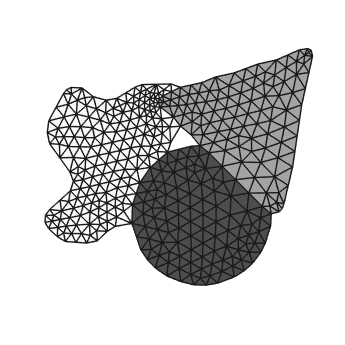

plotMeshes( vert, ele, tnum )

We can use function tricost to check the mesh quality. Function tricost is written by by Darren Engwirda.

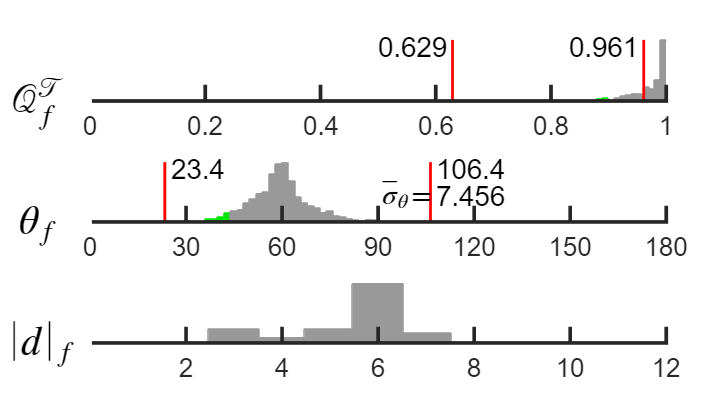

tricost( vert, ele, tnum );

## Note

If the mesh is quadratic trangular, the processing is slightly different.

After we got the mesh, we can use the functions in demo03 to export it.

## Unstructured quadrilateral mesh

We can use Gmsh to generate unstructured quadrilateral mesh. The method is similar. Please refer to 'Im2mesh_GUI Tutorial.pdf' and Gmsh manual about how to choose meshing parameters.

% setup parameters
opt.sizeMin = 0.1;
opt.sizeMax = 6;
opt.algthm = 8;
opt.recombAll = 1;
opt.recombAlgthm = 3;
opt.eleOrder = 1;

path_to_geo = 'gmshTemp.geo';
printGeo( phaseLoops, point, line, opt, path_to_geo );

path_to_m = 'gmshTemp.m';
verbosity = 3;
str=sprintf('"%s" "%s" -o "%s" -v %i -save', ... 
			path_to_gmsh, path_to_geo, path_to_m, verbosity );
system(str);

Gmsh will generate a m file. When we run the m file, we will see a struct variable 'msh' in the workspace of MATLAB.

% run m file
run(path_to_m)
msh

msh = struct with fields:
    nbNod: 871
      POS: [871×3 double]
      MAX: [87.2400 77.4400 0]
      MIN: [4.6900 4.4500 0]
    QUADS: [806×5 double]


Before ploting the mesh, we need to do some processing to the mesh data. 

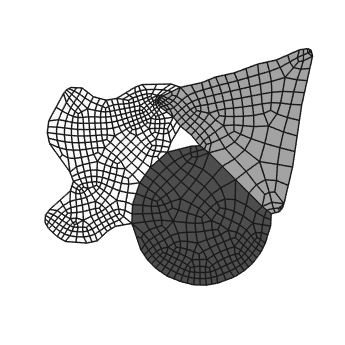

vert = msh.POS(:,1:2);
ele = msh.QUADS(:,1:end-1);
tnum = msh.QUADS(:,end);

% flip for correct signs
area = quadarea( vert, ele );
ele(area<0.,:) = ele( area<0., [1,4,3,2] );

plotMeshes( vert, ele, tnum )

Awesome!

We can use function [MeshQualityQuads](https://www.mathworks.com/matlabcentral/fileexchange/33108-unstructured-quadrilateral-mesh-quality-assessment) (written by Allan Peter Engsig-Karup) to evaluate mesh quality.

[q,theta] = MeshQualityQuads( ele, vert(:,1), vert(:,2) );
q_mean = mean(q)

q_mean = 0.6407

After we got the mesh, we can use the functions in demo03 to export it.

## Note

If the mesh is quadratic quadrilateral, the processing is slightly different.

% reset image size
set(groot, 'DefaultFigurePosition', 'factory')

% end of demo